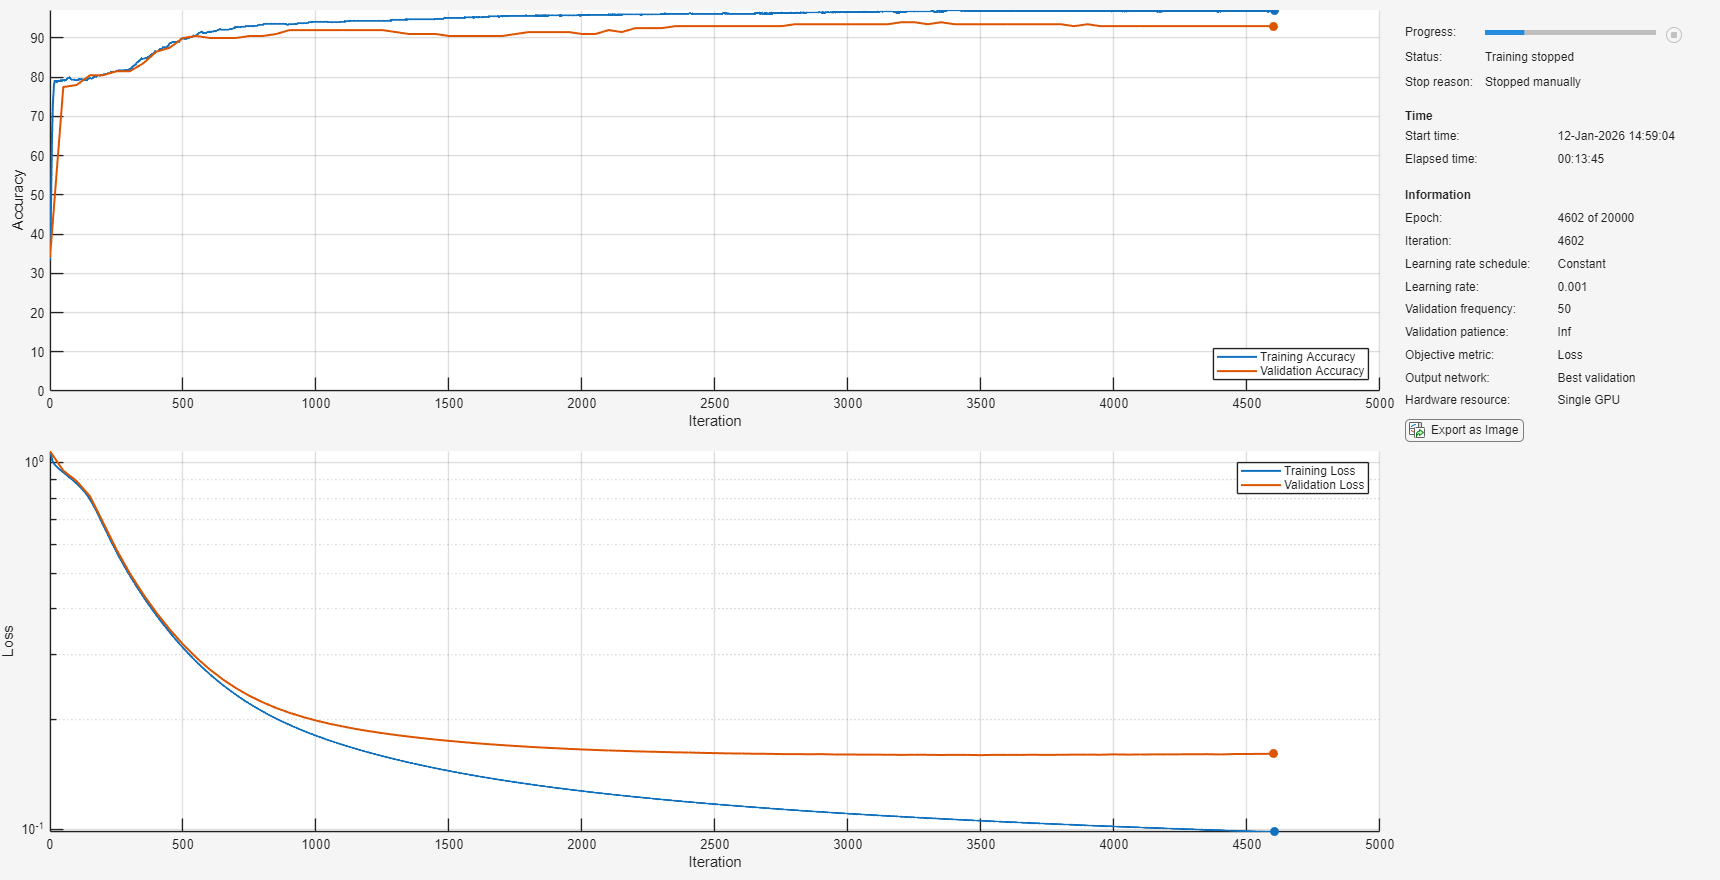


%
% DESCRIPTION
%   Demonstrates training a neural network to play Pong via supervised learning.
%   A synthetic dataset of game states and "optimal" actions is generated using
%   a simple heuristic: the paddle returns to center when the ball is far
%   (ballX < 0.7) and tracks the ball's y-position when the ball is near.
%   The network uses a feature input layer and fully connected layers with tanh
%   activations, and is trained with 'trainnet'. Finally, an interactive Pong
%   game runs with the user controlling the left paddle (arrow keys) and the
%   trained network controlling the right paddle.
%
% REQUIREMENTS
%   - MATLAB R2023b or later is recommended
%   - Deep Learning Toolbox
%   - (Optional) Custom weight initializer functions must exist on the MATLAB path:
%         customWeights1_git, customWeights2_git, customWeights3_git
%     These are referenced below via function handles. If you do not provide
%     them, replace the initializers with built-ins before running (doing so
%     would change code, so not included here).
%
% USAGE
%   1) Run this script to train:
%        >> PongSupervisedLearning
%   2) After training, play the game by running in the Command Window:
%        >> playPong(net, ballSpeed, maxBounceAngle)
%
% NOTES
%   - Ball speed is set by 'ballSpeed'. On paddle collision, the vertical
%     deflection scales with contact offset; max deflection is 'maxBounceAngle'.
%   - This file is formatted for public repositories: license header, clearer
%     documentation, and non-functional comment edits only.

%% Clear workspace and set random seed for reproducibility
clear; clc;
rng(1);

%% Ball speed and bounce parameters (tweak these to control game difficulty)
ballSpeed = 0.02;          % Base speed of the ball (used in training and simulation)
maxBounceAngle = pi/4;     % Maximum bounce angle (in radians) when hitting a paddle

%% Generate the training dataset
% Each training example consists of 5 features:
%   [ballX, ballY, ballVelX, ballVelY, paddleY]
% and one label among three classes: 'Up', 'Down', or 'Stay'.
numSamples = 1000;
[features, labels] = generateTrainingData(numSamples, ballSpeed);

%% Split data into training and validation sets (80/20 split)
numTrain = round(0.8 * numSamples);
trainFeatures = features(1:numTrain, :);
trainLabels   = labels(1:numTrain);
valFeatures   = features(numTrain+1:end, :);
valLabels     = labels(numTrain+1:end);

%% Create the neural network architecture
% The network has:
%   - A feature input layer (input size = 5)
%   - Two fully connected layers with tanh activations
%   - A final fully connected layer with softmax activation.
layers = createPongNetwork();

%% Define training options (do not change this code)
options = trainingOptions('adam', ...
    'MaxEpochs', 20000, ...             % Adjust the number of epochs as needed
    'MiniBatchSize', 1000, ...
    'ValidationData', {valFeatures, valLabels}, ...
    'Plots', 'training-progress', ...
    'Verbose', 0, 'Metrics', 'accuracy');
net = dlnetwork(layers);

%% Train the network using trainnet
[net,tr] = trainnet(trainFeatures, trainLabels, net, 'crossentropy', options); 


%% Evaluate the trained network on the validation set
predictedLabels = predict(net, valFeatures);
[~, predictedIndices] = max(predictedLabels, [], 2);
accuracy = sum(predictedIndices == grp2idx(valLabels)) / numel(valLabels);
fprintf('Validation accuracy: %.2f%%\n', accuracy * 100);

Validation accuracy: 93.50%


%% Play Pong using the trained network and user control
% The user controls the left paddle via the arrow keys, while the trained
% network controls the right paddle.
% Run the following in the Command Window (kept commented by design):
% playPong(net, ballSpeed, maxBounceAngle);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Helper Function: generateTrainingData
function [features, labels] = generateTrainingData(numSamples, ballSpeed)
    % Generates a synthetic dataset reflecting the control strategy.
    %
    % Features:
    %   - ballX: Horizontal position of the ball (0..1)
    %   - ballY: Vertical position of the ball (0..1)
    %   - ballVelX: Horizontal velocity (scaled by ballSpeed)
    %   - ballVelY: Vertical velocity (scaled by ballSpeed)
    %   - paddleY: Vertical position of the paddle (0..1)
    %
    % Heuristic labeling:
    %   - When the ball is far (ballX < 0.7), move paddle toward center (0.5).
    %   - When the ball is near (ballX >= 0.7), align with ball y-position.
    
    features = zeros(numSamples, 5);
    threshold = 0.1;        % Threshold for action based on position difference
    centerPos = 0.5;        % Desired center position
    labels = categorical(zeros(numSamples, 1), [0 1 2], ["Up", "Down", "Stay"]);
    
    for i = 1:numSamples
        % Random positions
        ballX   = rand;
        ballY   = rand;
        paddleY = rand;
        
        % Random velocity with magnitude ballSpeed
        theta = 2*pi*rand;
        ballVelX = ballSpeed * cos(theta);
        ballVelY = ballSpeed * sin(theta);
        
        features(i, :) = [ballX, ballY, ballVelX, ballVelY, paddleY];
        
        % Determine optimal action
        if ballX < 0.7
            % Far: move toward center (0.5)
            if paddleY < centerPos - threshold
                action = "Down";  % Increase paddleY to move toward center
            elseif paddleY > centerPos + threshold
                action = "Up";    % Decrease paddleY to move toward center
            else
                action = "Stay";
            end
        else
            % Near: track ball y-position
            if ballY < paddleY - threshold/2
                action = "Up";
            elseif ballY > paddleY + threshold/2
                action = "Down";
            else
                action = "Stay";
            end
        end
        labels(i) = categorical(action, ["Up", "Down", "Stay"]);
    end
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Helper Function: createPongNetwork
function layers = createPongNetwork()
    % Creates the layer architecture for the Pong neural network.
    % Input: 5 features; Output: 3 classes (Up, Down, Stay)
    inputSize = 5;
    numClasses = 3;
    
    layers = [
        featureInputLayer(inputSize, "Name", "input")
        fullyConnectedLayer(16e3, "Name", "fc1", ...
            'WeightsInitializer', @customWeights1_git, 'WeightLearnRateFactor', 0)
        tanhLayer("Name", "relu1")  % tanh activation; name preserved
        fullyConnectedLayer(16e3, "Name", "fc2", ...
            'WeightsInitializer', @customWeights2_git, 'WeightLearnRateFactor', 0)
        tanhLayer("Name", "relu2")  % tanh activation; name preserved
        fullyConnectedLayer(numClasses, "Name", "fc3", ...
            'WeightsInitializer', @customWeights3_git, 'WeightLearnRateFactor', 0)
        softmaxLayer("Name", "softmax")
    ];
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Helper Function: playPong
function playPong(net, ballSpeed, maxBounceAngle)
    % Simulates a simple Pong game where the user controls the left paddle
    % (arrow keys) and the trained network controls the right paddle.
    % Bounce vertical component is proportional to contact offset, limited by
    % maxBounceAngle.
    
    % Game state initialization:
    ballPos = [0.5, 0.5];        % [x, y] ball position (normalized)
    theta = 2*pi*rand;           % Random initial angle
    ballVel = ballSpeed * [cos(theta), sin(theta)];
    
    userPaddleY = 0.5;           % User (left paddle) vertical position
    userPaddleX = 0.05;          % Left paddle x position (fixed)
    netPaddleY = 0.5;            % Network (right paddle) vertical position
    paddleHeight = 0.2;          % Paddle height (normalized)
    paddleWidth  = 0.02;         % Paddle width (normalized)
    ballRadius   = 0.02;         % Ball radius (normalized)
    
    % Network paddle x position (right side)
    netPaddleX = 1 - userPaddleX - paddleWidth;
    
    % Initialize scores
    userScore = 0;
    netScore  = 0;
    
    % Open the Pong game in a new window and set up the axis
    fig = figure('Name', 'Pong Game', 'NumberTitle', 'off', 'WindowStyle', 'normal', ...
        'KeyPressFcn', @keyPressCallback);
    ax = axes('Parent', fig);
    axis(ax, [0 1 0 1]);
    axis(ax, 'equal');
    set(ax, 'XTick', [], 'YTick', []);  % Remove axis tick marks
    box(ax, 'on');
    
    % Draw game boundary (walls)
    wallRect = rectangle(ax, 'Position', [0, 0, 1, 1], 'EdgeColor', 'k', 'LineWidth', 2); %#ok<NASGU>
    
    % Draw initial paddles and ball
    userPaddleRect = rectangle(ax, 'Position', [userPaddleX, userPaddleY - paddleHeight/2, paddleWidth, paddleHeight], 'FaceColor', 'b');
    netPaddleRect  = rectangle(ax, 'Position', [netPaddleX, netPaddleY - paddleHeight/2, paddleWidth, paddleHeight], 'FaceColor', 'g');
    ballCircle     = rectangle(ax, 'Position', [ballPos(1)-ballRadius, ballPos(2)-ballRadius, 2*ballRadius, 2*ballRadius], ...
                               'Curvature', [1 1], 'FaceColor', 'r');
    
    % Display scoreboard at the top
    scoreText = text(ax, 0.5, 0.97, sprintf('User: %d    Network: %d', userScore, netScore), ...
                     'HorizontalAlignment', 'center', 'FontSize', 14, 'FontWeight', 'bold');
    title(ax, 'Pong: Use Up/Down arrows. Close window or press Ctrl+C to exit');
    
    % Paddle movement step sizes
    userDelta = 0.01;      % User paddle movement step size
    netDelta  = 0.01;      % Network paddle movement step size
    
    % Initialize variable to store the user's action
    userAction = "Stay";
    
    % Key press callback to update userAction
    function keyPressCallback(~, event)
        switch event.Key
            case 'uparrow'
                userAction = "Up";
            case 'downarrow'
                userAction = "Down";
            otherwise
                userAction = "Stay";
        end
    end

    % Simulation loop
    while ishandle(fig)
        % ----- Update User Paddle (Left) -----
        if userAction == "Up"
            userPaddleY = max(userPaddleY - userDelta, paddleHeight/2);
        elseif userAction == "Down"
            userPaddleY = min(userPaddleY + userDelta, 1 - paddleHeight/2);
        end
        userAction = "Stay";  % Reset action until next key press
        
        % ----- Update Network Paddle (Right) -----
        % Use network prediction with state vector: [ballX, ballY, ballVelX, ballVelY, netPaddleY]
        state = [ballPos, ballVel, netPaddleY];
        pred = predict(net, state);
        [~, predClass] = max(pred, [], 2);
        if predClass == 1
            netAction = "Up";
        elseif predClass == 2
            netAction = "Down";
        else
            netAction = "Stay";
        end
        if netAction == "Up"
            netPaddleY = max(netPaddleY - netDelta, paddleHeight/2);
        elseif netAction == "Down"
            netPaddleY = min(netPaddleY + netDelta, 1 - paddleHeight/2);
        end
        
        % ----- Update Ball Position -----
        ballPos = ballPos + ballVel;
        
        % Bounce off top and bottom walls
        if ballPos(2) - ballRadius <= 0 || ballPos(2) + ballRadius >= 1
            ballVel(2) = -ballVel(2);
        end
        
        % ----- Collision with User Paddle (Left) -----
        if ballPos(1) - ballRadius <= userPaddleX + paddleWidth
            if ballPos(2) >= userPaddleY - paddleHeight/1.5 && ballPos(2) <= userPaddleY + paddleHeight/1.5
                relIntersect = (ballPos(2) - userPaddleY) / (paddleHeight/2);
                angle = relIntersect * maxBounceAngle;
                ballVel(1) = abs(ballSpeed * cos(angle));  % Bounce rightward
                ballVel(2) = ballSpeed * sin(angle);
            elseif (ballPos(2) + ballRadius >= userPaddleY + paddleHeight/2) && (ballPos(2) - ballRadius < userPaddleY + paddleHeight/2)
                angle = maxBounceAngle;
                ballVel(1) = abs(ballSpeed * cos(angle));
                ballVel(2) = ballSpeed * sin(angle);
            else
                % Ball missed user paddle: network scores
                netScore = netScore + 1;
                set(scoreText, 'String', sprintf('User: %d    Network: %d', userScore, netScore));
                pause(0.5);
                ballPos = [0.5, 0.5];
                theta = (pi/4)*rand;
                ballVel = ballSpeed * [cos(theta), sin(theta)];
            end
        end
        
        % ----- Collision with Network Paddle (Right) -----
        if ballPos(1) + ballRadius >= netPaddleX
            if ballPos(2) >= netPaddleY - paddleHeight/1.5 && ballPos(2) <= netPaddleY + paddleHeight/1.5
                relIntersect = (ballPos(2) - netPaddleY) / (paddleHeight/2);
                angle = relIntersect * maxBounceAngle;
                ballVel(1) = -abs(ballSpeed * cos(angle));  % Bounce leftward
                ballVel(2) = ballSpeed * sin(angle);
            elseif (ballPos(2) + ballRadius >= netPaddleY + paddleHeight/2) && (ballPos(2) - ballRadius < netPaddleY + paddleHeight/2)
                angle = maxBounceAngle;
                ballVel(1) = -abs(ballSpeed * cos(angle));
                ballVel(2) = ballSpeed * sin(angle);
            else
                % Ball missed network paddle: user scores
                userScore = userScore + 1;
                set(scoreText, 'String', sprintf('User: %d    Network: %d', userScore, netScore));
                pause(0.5);
                ballPos = [0.5, 0.5];
                theta = (pi/4)*rand;
                ballVel = ballSpeed * [cos(theta), sin(theta)];
            end
        end
        
        % ----- Update Graphics -----
        set(userPaddleRect, 'Position', [userPaddleX, userPaddleY - paddleHeight/2, paddleWidth, paddleHeight]);
        set(netPaddleRect, 'Position', [netPaddleX, netPaddleY - paddleHeight/2, paddleWidth, paddleHeight]);
        set(ballCircle, 'Position', [ballPos(1)-ballRadius, ballPos(2)-ballRadius, 2*ballRadius, 2*ballRadius]);
        drawnow;
        pause(0.01);
    end
end
